# Generate Healthy Fan Signals

Define sample rate and time vector.

fs = 2400;
n = 2400;
t = (0:n-1)/fs;
t = t';

Create variable for fan rotation speed (4000 rpm).

fr = 4000/60;

Create signal with fundamental frequency and 2 harmonics. Vary amplitudes based on real-world data.

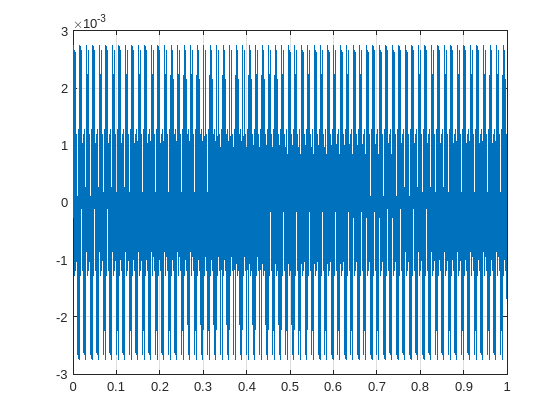

sig = 1e-3*(sin(2*pi*fr*t) + 0.5*sin(2*pi*3*fr*t) + 2*sin(2*pi*4*fr*t));
plot(t, sig)
grid on